# Partial ressure first order reaction

P0 = 55;
Ea = 77e3;
A = 1e14;
R = 8.314;
T = 293.15:303;
%A0 = 0.25;
t = 1:0.25:4

t =     1.0000    1.2500    1.5000    1.7500    2.0000    2.2500    2.5000    2.7500    3.0000    3.2500    3.5000    3.7500    4.0000


[X,Y] = meshgrid(t,T);

k = A*exp(-Ea./(R*Y));
Z = P0*exp(-k.*X)  %Pa = Z

Z =     8.2053    5.0995    3.1693    1.9697    1.2241    0.7608    0.4728    0.2939    0.1826    0.1135    0.0705    0.0438    0.0272
    6.6132    3.8942    2.2932    1.3503    0.7952    0.4682    0.2757    0.1624    0.0956    0.0563    0.0332    0.0195    0.0115
    5.2101    2.8905    1.6036    0.8896    0.4935    0.2738    0.1519    0.0843    0.0468    0.0259    0.0144    0.0080    0.0044
    4.0035    2.0795    1.0802    0.5611    0.2914    0.1514    0.0786    0.0408    0.0212    0.0110    0.0057    0.0030    0.0015
    2.9934    1.4458    0.6983    0.3373    0.1629    0.0787    0.0380    0.0184    0.0089    0.0043    0.0021    0.0010    0.0005
    2.1719    0.9682    0.4316    0.1924    0.0858    0.0382    0.0170    0.0076    0.0034    0.0015    0.0007    0.0003    0.0001
    1.5250    0.6223    0.2539    0.1036    0.0423    0.0173    0.0070    0.0029    0.0012    0.0005    0.0002    0.0001    0.0000
    1.0330    0.3824    0.1416    0.0524    0.0194    0.0072    0.0027    0.001

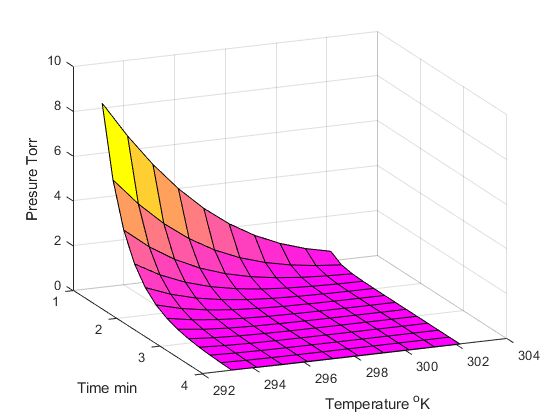

surf(X,Y,Z)
grid on
xlabel('Time min')
ylabel('Temperature ^oK')
zlabel('Presure Torr')
view(67,22)
colormap spring